## **AERO40003 Computing and Numerical Methods 1**

## **Coursework Project Part 2**

## ** 2020-2021**

## **Dr. Elnaz Naghibi**

## **Due Date: 26 March 2021**

### **Question 1 [5%]**

Plot the function$f\left(x\right)=e^x -3x^2$  and show that it has 3 roots. An obvious arrangement to find the roots using fixed-point method is $x=g\left(x\right)=\pm \sqrt{\frac{e^x }{3}}$. Show that convergence is to the root near -0.5 if we begin with $x_0 =0$ and use the negative value of $g\left(x\right)$. Also, show that convergence to the second root near 1.0 is obtained if $x_0 =0$ and the positive value of $g\left(x\right)$ is used. Show that this form does not converge to the third root near 4.0 even though a starting value very close to the root is used. Find a different arrangement that will converge to the root near 4.0. Hint: Evaluate $g^{\prime } \left(x\right)$ for $x$ values close to the required roots. Show the convergence to each root using appropriate plots and provide the code for the fixed point method. Consider the tolerance value to be equal to 1e-6.

**Answer:**

You can use this space to explain the answers and include equations as needed using either Latex code or the live script equation editor from the tab "insert".

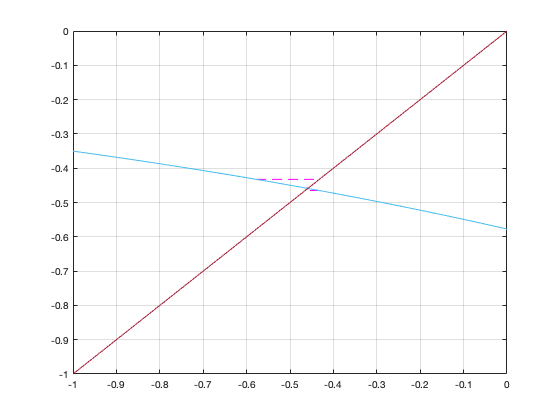

clear all
clc
clf

% Assigning the given function and its arrangement
func = @(x) exp(x)-(3*x^2);
positiveG = @(x) sqrt((exp(x))/3);
negativeG = @(x) -sqrt((exp(x))/3);
y = @(x) x;

% Calculating and Plotting root 1 using initial guess 0 
xcurr = 0;
xnext = negativeG(xcurr);
tol = 1e-6;
figure

while abs(xcurr-xnext)>=tol
    xcurr = xnext;
    xnext = negativeG(xcurr);
    plot([xcurr,xnext],[xcurr,xnext],'m--')
    plot([xcurr,xnext],[xnext,xnext],'m--')
    hold on
end

fplot(negativeG);
hold on 
fplot(y);
xlim([-1 0]);
ylim([-1 0]);
hold off
grid on


disp(['The 1st root using initial guess 0 is: ',num2str(xcurr)]);

The 1st root using initial guess 0 is: -0.45896



% Checking for convergence of root 1 using initial guess and 
% derivative of argument

gDer = @(x) exp(x/2)/(2*sqrt(3));
gderivative = gDer(0);

if gderivative<1
    
    disp(['Substituting the root into the derivative of the function gives: ',num2str(gderivative), 'it converges.']);
    
else 
    
    disp(['Substituting the root into the derivative of the function gives: ',num2str(gderivative), 'it diverges.']);
    
end

Substituting the root into the derivative of the function gives: 0.28868it converges.


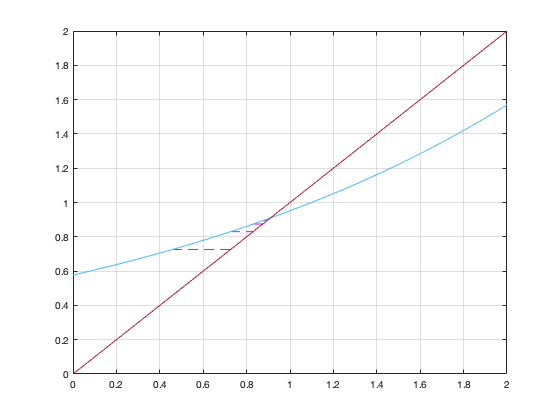

    
% Calculating and Plotting root 2 using initial guess 0 
xcurr1 = 0;
xnext1 = positiveG(xcurr);
figure

while abs(xcurr1-xnext1)>=tol
    xcurr1 = xnext1;
    xnext1 = positiveG(xcurr1);
    plot([xcurr1,xnext1],[xcurr1,xnext1],'m--')
    plot([xcurr1,xnext1],[xnext1,xnext1],'m--')
    hold on
end

fplot(positiveG);
hold on 
fplot(y);
xlim([0 2]);
ylim([0 2]);
hold off 
grid on


disp(['The 2nd root using initial guess 0 is: ',num2str(xcurr1)]);

The 2nd root using initial guess 0 is: 0.91001



% Checking for convergence of root 2 using initial guess and 
% derivative of argument

gderivative = gDer(0);

if gderivative<1
    
    disp(['Substituting the root into the derivative of the function gives: ',num2str(gderivative), 'it converges.']);
    
else 
    
    disp(['Substituting the root into the derivative of the function gives: ',num2str(gderivative), 'it diverges.']);
    
end

Substituting the root into the derivative of the function gives: 0.28868it converges.


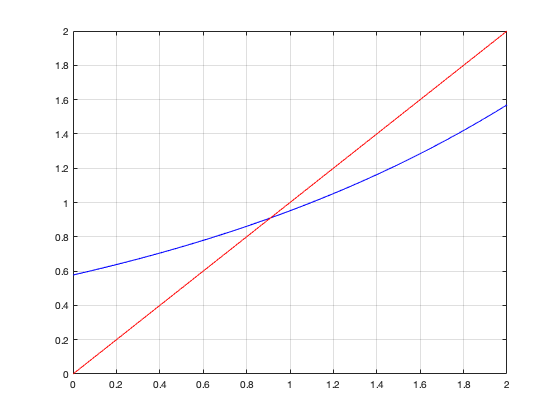


% Calculating and Plotting root 3 using initial guess 3.8 
xcurr3 = 3.8;
xnext3 = positiveG(xcurr3);
figure

while abs(xcurr3-xnext3)>=tol
    xcurr3 = xnext3;
    xnext3 = positiveG(xcurr3);
    plot([xcurr3,xnext3],[xcurr3,xnext3],'m--')
    plot([xcurr3,xnext3],[xnext3,xnext3],'m--')
    hold on
end

fplot(positiveG,'b');
hold on 
fplot(y,'r');
xlim([0 2]);
ylim([0 2]);
hold off 
grid on 


% Checking for convergence of root 3 using initial guess and 
% derivative of argument

gderivative = gDer(3.8);

if gderivative<1
    
    disp(['Substituting the root into the derivative of the function gives: ',num2str(gderivative), 'it converges.']);
    
else 
    
    disp(['Substituting the root into the derivative of the function gives: ',num2str(gderivative), 'it diverges.']);
    
end

Substituting the root into the derivative of the function gives: 1.9301it diverges.



% Calculating and Plotting root 3 using a different arrangement

newf = @(x) log(3*(x^2));
xcurr4 = 3.8;
xnext4 = newf(xcurr4);

while abs(xcurr4 - xnext4) >= tol
    xcurr4 = xnext4;
    xnext4 = newf(xcurr4);
    plot([xcurr4,xnext4],[xcurr4,xnext4],'m--')
    plot([xcurr4,xnext4],[xnext4,xnext4],'m--')
    hold on   
end

fplot(newf);

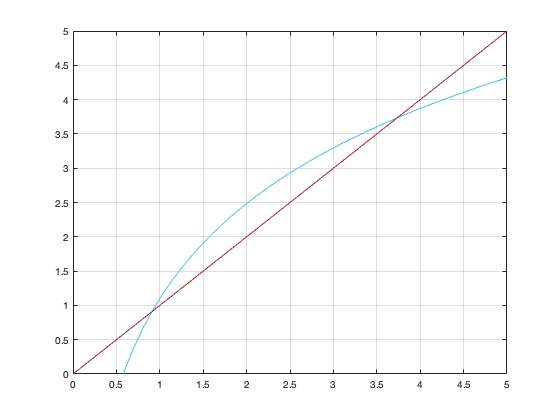

hold on
fplot(y)
xlim([0 5])
ylim([0 5])
hold off
grid on


disp(['The 3rd root using the different arrangement and initial guess 3.8 is: ',num2str(xcurr4)]);

The 3rd root using the different arrangement and initial guess 3.8 is: 3.7331


newfderv = @(x) (2/x);

% Checking for convergence of root 4 using initial guess and 
% derivative of new argument
gderivative = newfderv(3.8);

if gderivative<1
    
    disp(['Substituting the root into the derivative of the function gives: ',num2str(gderivative), 'it converges.']);
    
else 
    
    disp(['Substituting the root into the derivative of the function gives: ',num2str(gderivative), 'it diverges.']);
    
end

Substituting the root into the derivative of the function gives: 0.52632it converges.


### **Question 2 [10%]**

**Part a: [5%]**

Calculate Legendre polynomial of degree 5 using equation 16 in Handout_4 and MATLAB symbolic toolbox. Compare your resulting polynomial with "legendreP" function in MATLAB. Plot this function in the interval $\left\lbrack -1,1\right\rbrack$ and calculate its roots $\eta_i$. Calculate weighting coefficients $w_i$ using the definition in equation 21. Using  $\eta_i$ and $w_i$, calculate the integral of  $\int_{-1}^2 \left({\textrm{ax}}^9 +{\textrm{bx}}^4 +\textrm{cx}\right)\;\textrm{dx}$ for arbitrary values of $a,b,c$ and show that it will be the same as its analytical value.

**Answer:**

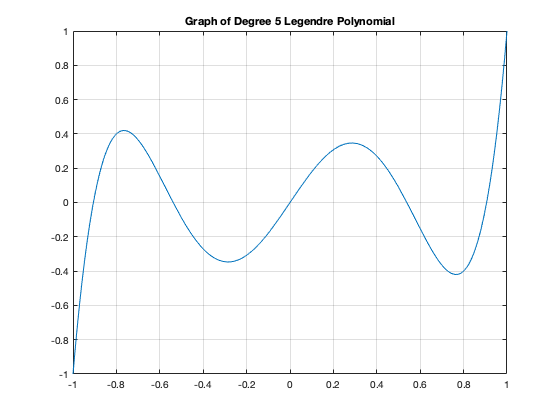

% Legendre calculated without using LegendreP function

syms x a b c 

y = ((x^2)-1)^5;    % function that was given is assigned
N = 5;              % Degree of polynomial
f = diff(y,x,N);
fact = factorial(N);

legendre1 = (1/((2^N)*fact))*f;

% Legendre calculated using LegendreP function

legendre2 = legendreP(N,x); %finds 5th degree legendre of x

% Plots the legendre polynomial over range [-1,1]

figure 
fplot(legendre2,[-1 1]);
title('Graph of Degree 5 Legendre Polynomial');
xlim([-1 1]);
grid on


% Calculating root of legendre polynomial

roots = vpasolve(legendre2==0,x);

% Calculating the weightings

w = zeros(1,5);
legendre2derv = diff(legendre2,x); %derivative of legendre polynomial

for i = 1:length(roots) 
    
    g = subs(legendre2derv,x,roots(i)); %Substituting root S into derivative of legendre
    w(i) = (2/(1-(roots(i))^2))*((g)^-2);
    
end

% Calculating integral of given equation for arbitrary values of a,b,c

sum = 0;

% Given function but over the bounds [-1,1]
y1 = (3/2)*(a*((1/2)+(3/2)*x)^9+b*((1/2)+(3/2)*x)^4+c*((1/2)+(3/2)*x)); 

% Original given function 
y2 = (a*x^9+b*x^4+c*x);

% Calculating integral using roots and weightings
for j = 1:length(roots)
    
    g1 = subs(y1,x,roots(j)); 
    sum = sum+w(j)*g1; 
    
end

disp('The integral using roots and weightings is: ');

The integral using roots and weightings is: 


disp(sum);

$$102.29999999999999900757950214508\,a+6.5999999999999999635806461558196\,b+1.5000000000000000003700743415417\,c$$


% Analytical value of the given function

AnalyticInt = vpa(int(y2,x,-1,2)); 

disp('The analytical value of the integral: ');

The analytical value of the integral: 


disp(AnalyticInt);

$$102.3\,a+6.6\,b+1.5\,c$$

**Part b: [5%]**

Use Simpson integration scheme to calculate the below integral for $n=10,20,40,80$. Compare the results with the analytical value and calculate the error in each case. Provide the code for the integration scheme and error calculation.


$$\int_0^1 x\;e^x \;\textrm{dx}$$


**Answer:**

% Method to find integral using simpson method for n bars over the bounds 0 and 1

syms x

upB = 1;                % Assigns upper bound
lowB = 0;               % Assigns lower bound
bars=[10,20,40,80];     % Assigns the different bounds to try

for p = 1:length(bars)  %loop that iterates through bars array
    
    n=bars(p);
    h = (upB-lowB)/n;   % h is calculated for n bars
    fun = x*exp(x);     % function that was given is assigned
    sum2 = 0;   

    for k = 0:n               % loop iterates over each bar in n bars
    
        sub = lowB+(k*h);     
        g2 = subs(fun,x,sub); % substitutes value above into given function
    
        if k==0 | k==n        % IF statement to assign coefficient. Either 1, 2 or 4
           sum2 = sum2+g2;
        elseif mod(k,2)==0    
           sum2 = sum2+(2*g2);
        else 
           sum2 = sum2+(4*g2); 
        end
    
    end

    finalSum = (h/3)*sum2;    % Takes total sum and multiplies by h/3

    % Analytical method for calculating integral over bounds 0 and 1
    AnalyticInt2 = int(fun,x,0,1);

    %error calculation
    error = ((vpa(finalSum)-AnalyticInt2)/AnalyticInt2)*100; %equation for calculating error
    output = ['The percentage error between analytical solution and simpson method using ',num2str(double(n)),' bars is: ',num2str(double(error)),'%'];
    disp(output);
    
end

The percentage error between analytical solution and simpson method using 10 bars is: 0.00043665%
The percentage error between analytical solution and simpson method using 20 bars is: 2.7326e-05%
The percentage error between analytical solution and simpson method using 40 bars is: 1.7084e-06%
The percentage error between analytical solution and simpson method using 80 bars is: 1.0678e-07%


### **Question 3 [10%]**

**Part a: [5%]**

Use Chebyshev distribution to sample 5 values of function $f\left(x\right)=\frac{1}{\left(e^{x^2 } +e^{{-x}^2 } \right)}$ in the interval $\left\lbrack -2,2\right\rbrack$. Write a code to calculate the Newton interpolating polynomial passing though these points. Increase the number of points to 15 and rebuild the polynomial. Provide graphs to compare the original function and the interpolating polynomial and report the Euclidean norm of error in each case. 

**Answer:**

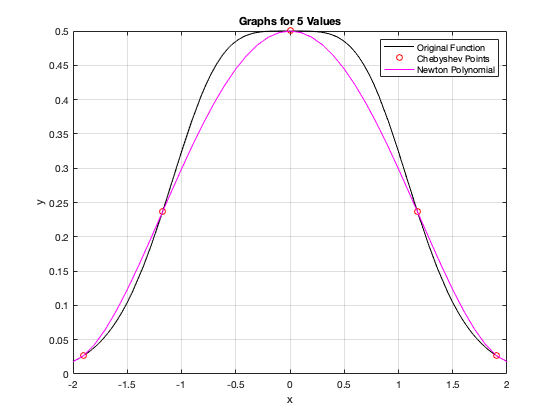

clear all
clc
clf
format short
syms a b d x
fx = @(x) 1./(exp(x.^2)+(exp(-(x.^2)))); % Assigning the given function
q = [-2:0.1:2]; % range of x coordinates 

% Calculating x and y values for 5 chebyshev points
[c5p,c5y,c5x]=chebyshev(5,fx);

% Calculating x and y values for 15 chebyshev points
[c15p,c15y,c15x]=chebyshev(15,fx);

% Calculating coefficients of Newton Interpolating Polynomial
coeff5 = coefficients(c5x,c5y);
coeff15 = coefficients(c15x,c15y);

% Plotting Original Graph for 5 chebyshev points
fplot(fx,'k');

% Plotting 5 Chebyshev Points
hold on
plot(c5x,c5y,'ro');

fxval = fx(q); %y values of original graph and eq is y value of newton polynomial graph

% Plotting Newton Interpolating Polynomial Graph of 5 points
hold on
[np5] = polygraph(coeff5,c5x,q); 
plot(q,np5,'m');
legend('Original Function','Chebyshev Points', 'Newton Polynomial');
title('Graphs for 5 Values')
xlabel('x');
ylabel('y')
xlim([-2 2]); 
ylim([0 0.5]);
hold off
grid on


% Calculating euclidean norm for 5 Chebyshev Points
outputE1 = euclid(fxval,np5);
disp(outputE1);

The Euclidean norm of error is 0.16404


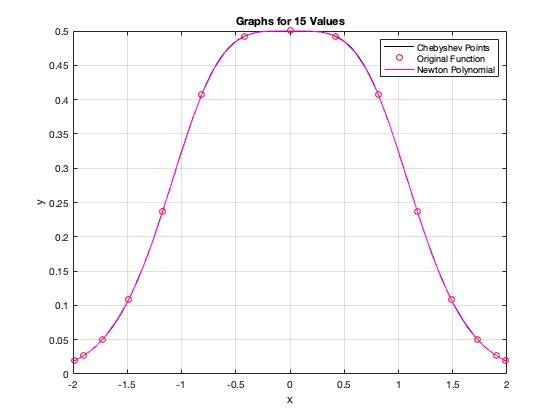


% Plotting Original Graph for 15 chebyshev points
fplot(fx,'k');
hold on

% Plotting 15 Chebyshev Points
plot(c15x,c15y,'ro');
hold on

% Plotting Newton Interpolating Polynomial Graph of 15 points
[np15] = polygraph(coeff15,c15x,q);
plot(q,np15,'m');
legend('Chebyshev Points','Original Function', 'Newton Polynomial');
title('Graphs for 15 Values')
xlabel('x');
ylabel('y');
xlim([-2 2]); 
ylim([0 0.5]);
hold off
grid on


% Calculating euclidean norm for 15 values
outputE2 = euclid(fxval,np15);
disp(outputE2);

The Euclidean norm of error is 0.0028357


**Part b: [5%]**

Use the 5 equally spaced sample points for the function in part a and find the cubic splines passing through these points. Calculate the Euclidean norm of the error in this case and provide a graph to compare the original function and the cubic splines.

**Answer:**

clf
N = 5;
fx = @(x) 1./(exp(x.^2)+(exp(-(x.^2)))); % Assigning the given function
x = linspace(-2,2,5); % Creating 5 equally spaced sample points
y = fx1(xcoord); % Y coordinates of the 5 sample points

% Assigning values to matrix A

v = [2/3 2/3 2/3];
A = diag(v);

for n = 1:N-2
    for m = 1:N-2
        if n~=m
            A(n,m)=1/6;
        end
    end
end

A(1,3) = 0;
A(3,1) = 0;

% Assigning values to matrix B

B = zeros(3,1);

for t = 1:N-2
    
    B(t) = (ycoord(t+2)-2*ycoord(t+1)+ycoord(t));
    
end

X = A\B;

Deltax = 1;

curvatures = [0;X;0];

% Creating Cubic Spline

for j=2:N
    x_local = [x(j-1):(Deltax/1000):x(j)];
    for k=1:length(x_local)
        ypoly(k) = (curvatures(j-1)/6)*((x(j)-x_local(k))^3/(x(j)-x(j-1)) - (x(j)-x(j-1))*(x(j)-x_local(k))) ...
        +(curvatures(j)/6)*((x_local(k)-x(j-1))^3/(x(j)-x(j-1))-(x(j)-x(j-1))*(x_local(k)-x(j-1))) ...
        +y(j-1)*((x(j)-x_local(k))/(x(j)-x(j-1)))+y(j)*((x_local(k)-x(j-1))/(x(j)-x(j-1)));
    end
    % Plotting Cubic Spline
    cubspine = plot(x_local,ypoly,'r')
    hold on
end

cubspine =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×1001 double]
              YData: [1×1001 double]
              ZData: [1×0 double]

  Show all properties


cubspine =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×1001 double]
              YData: [1×1001 double]
              ZData: [1×0 double]

  Show all properties


cubspine =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×1001 double]
              YData: [1×1001 double]
              ZData: [1×0 double]

  Show all properties


cubspine =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×1001 double]
              YData: [1×1001 double]
              ZData: [1×0 double]

  Show all properties


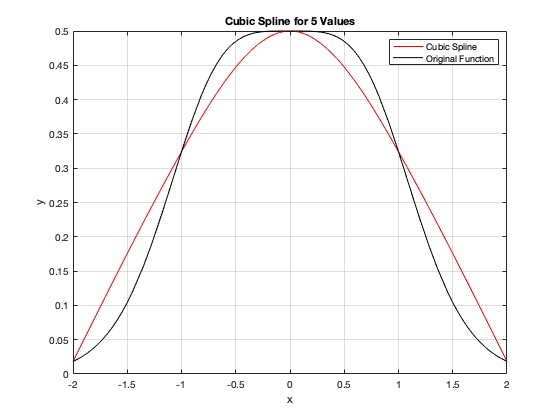


% Plotting the original function

fgraph = fplot(fx1,'k');
title('Cubic Spline for 5 Values')
xlabel('x');
ylabel('y');
legend([cubspine,fgraph],'Cubic Spline','Original Function');
xlim([-2 2]); 
ylim([0 0.5]);
grid on


% Calculating Euclidean Norm

xCub = linspace(-2,2,1001);
fxNew = fx1(xCub);
outputE3 = euclid(fxNew,ypoly);

The Euclidean norm of error is 7.3828


disp(outputE3);

Functions utilized in Part 2 Coursework

function [poly] = coefficients(x,y);
% Function to determine coefficients for Newton Interpolating Polynomial
% x - x values for given chebyshev points
% y - y values for given chebyshev points
% poly - array of coefficients

    poly = y;

    for u=2:length(poly)
        poly(u:end) = (poly(u:end) - poly((u - 1):(end - 1))) ./ (x(u:end) - x(1:end - u + 1));
end

end

function [points,yC,xC] = chebyshev(val,fx)
% Function to create chebyshev x values and y values and plot original graph
% val - Number of Chebyshev Points
% points - Chebyshev points for limit [-1,1]
% xC - x coordinates of Chebyshev Points
% yC - y coordinates of Chebyshev Points
% fx - original given function

    points = [];
    chebyshevFunc = @(x) -cos(((2*x+1)/(2*(val-1)+2))*pi);

    for r = 0:val-1
    
      points(r+1) = chebyshevFunc(r);
    
    end
    
% Multiplied by 2 due to limits of graph
    xC = 2.*points;
    yC = fx(xC);
end

function [NPoly] = polygraph(c,cx,q)
% Function to create Newton Interpolating Polynomial 
% c - coefficients for polynomial
% cx - x coordinates of Chebyshev Points
% q - range of x coordinates
% NPoly - Y coordinates from Newton Interpolating Polynomial

t = c(1);
m=1;
NPoly=0;
q = [-2:0.1:2];
for i = 2:length(c)
    
    for j = 1:(i-1)
        
        m = m.*(q-cx(j));
        
    end
    
    val2 = c(i).*m;
    NPoly = NPoly+val2;
    m=1;
    
end

NPoly = t+NPoly;

end

function [outputE] = euclid(fxNew,NPoly)
% Function to calculate euclidean norm
% NPoly - Y coordinates from Newton Interpolatng Polynomial
% fxNew - Y coordinates from Original graph
% outputE - Statement to output to user

    errorval = norm(fxNew-NPoly);
    outputE = ['The Euclidean norm of error is ',num2str(errorval)];

end
